# Original files from test_prm_v1.m and test_rrt_v1.m

%

% test script for PRM and RRT

%

% - written by Jin Seob Kim

clc

clear

close all

## World space and Obstacles

% DIMENSIONS AND OBJECTS HAVE BEEN CHANGED FOR FASTER SIMULATION
% (Laptop was acting slow)
L_world = 50;



% multiple obstacles

N_obs = 1; % number of obstacles

B1 = [0 L_world/2 L_world/2 0;
    
L_world/4 L_world/4 (L_world+100)/4 (L_world+100)/4];



%B2 = [L_world/2 L_world L_world L_world/2;
    
%L_world/2+20 L_world/2+20 (L_world-20) (L_world-20)];



B = cell(1,N_obs);

B{1} = B1;

%B{2} = B2;

## PRM

N = 250;

K = 15;

p_init = [0.5;0.5];

p_goal = [L_world - 5;L_world - 5];

[Path, V_sort, G] = build_PRM(p_init, p_goal, N, K, B, L_world,L_world);

## RRT

N = 2500;

delta_q = 5;

tolerance = 3.0;

p_init = [0.5;0.5];

p_goal = [L_world - 5;L_world - 5];

%[Path, V_sort, Edges] = build_RRT(p_init, p_goal, N, delta_q, B, L_world,L_world, tolerance);

## show configuration

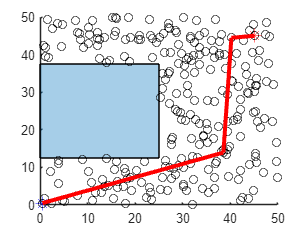

%You may add addition lines for visualizaton.

figure;

plot(polyshape(B1(1,:),B1(2,:)));

hold on

%plot(polyshape(B2(1,:),B2(2,:)));

plot(V_sort(1,:),V_sort(2,:),'ko');

plot(p_init(1),p_init(2),'b*','MarkerSize',10)

plot(p_goal(1),p_goal(2),'r*','MarkerSize',10)

hold on

axis([0 L_world 0 L_world]);

for ix = 1:size(Path,2)-1
    
    plot([Path(1,ix) Path(1,ix + 1)],[Path(2,ix) Path(2,ix + 1)],'r-','LineWidth',3)
    
    hold on
    
end